# Symbolic Operations in MATLAB

Most everything we've done this semester has been numerical. That is, we have used *variables* to store numeric values and have performed the ensuing numerical operations by manipulating the variables. MATLAB can also perform symbolic manipulation, and furthermore has built-in functions that help us move between the symbolic and numerical space.

### Defining Symbolic Variables

To define variables that we wish to be treated as symbols, we use the [syntax](https://www.mathworks.com/help/symbolic/syms.html?searchHighlight=syms&s_tid=srchtitle_syms_1)

Define the function $f = x^2-4$, where $x$ is a symbol

syms x
f = x^2 - 4

$$f = x^{2}-4$$

### Plotting Symbolic Variables

We can plot symbolic variables using [`fplot`](https://www.mathworks.com/help/symbolic/fplot.html?s_tid=doc_ta). The basic syntax is

Plot `f` in the domain $-5\leq x \leq 5$.

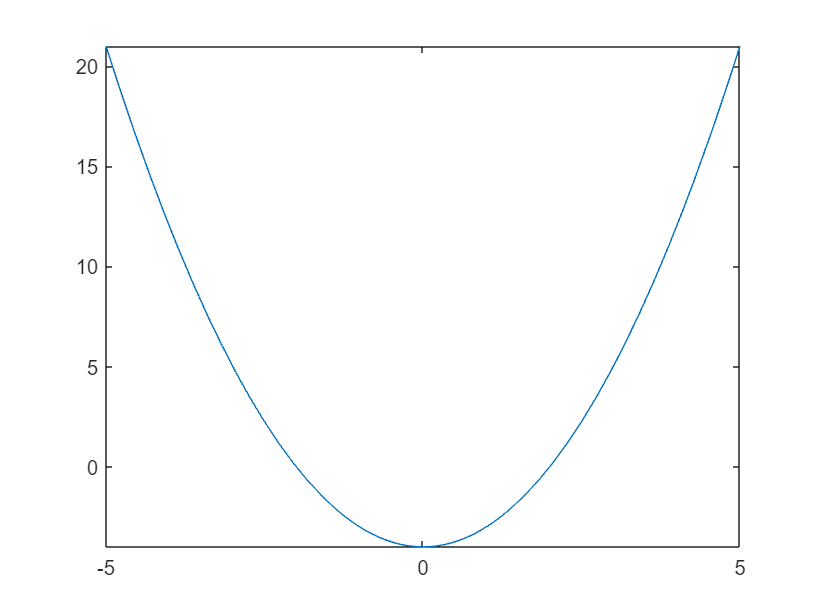

fplot(f,[-5,5])

## Useful Symbolic Mathematical Operations

You can find derivatives, definite or indefinite integrals, solve systems of equations, etc., using symbolic math in MATLAB. Please note that any answers you generate with be *symbols*, not *doubles* (i.e., numbers). You have to convert your symbolic answers to doubles if you want to treat them like numbers.

### Integration and Differentiation

Sometimes it is nice to use MATLAB to integrate and differentiate for you. In general this is most useful when you have ugly functions that are too tedious to integrate/differentiate by hand. Here, we'll do some examples we could easily check by hand if we wanted to verify MATLAB's results.

### Integration

You can symbolically integrate a function in MATLAB using the [`int`](https://www.mathworks.com/help/symbolic/sym.int.html?searchHighlight=int&s_tid=srchtitle_int_1) function. The general syntax for symbolically integrating `f` with respect to `var` on the interval `[a,b]` is

- if no bounds are given, this computes the indefinite integral

Compute the indefinite integral of $y=\sin{(t)}+7$, as well as the definite integral of $y$ for $0\leq t \leq \pi$.

syms t
y = sin(t) + 7

$$y = \sin\left(t\right)+7$$

int(y,t,0,pi)

$$ans = 7\,\pi +2$$

int(y,t)

$$ans = 7\,t-\cos\left(t\right)$$

Note that your answer is a *symbol* !!

### Differentiation

You can differentiate a symbolic variable using the [`diff`](https://www.mathworks.com/help/symbolic/diff.html?searchHighlight=diff&s_tid=srchtitle_diff_2) function. The general syntax for the $n^{\text{th}}$ derivative of `f` with respect to `var` is

Calculate the first and second derivatives of $y$.

diff(y,t,1)

$$ans = \cos\left(t\right)$$

diff(y,t,2)

$$ans = -\sin\left(t\right)$$

### Solving Symbolic Equations

Solving a system of 2 equations by hand is generally trivial. Solving a system of 3 equations by hand is generally annoying. Solving a system of 4 or more equations by hand is generally a waste of time--it's good to know how to do it, but you wouldn't want to spend your days like this. 

To solve general symbolic equations in MATLAB, we use the [`solve`](https://www.mathworks.com/help/symbolic/sym.solve.html?s_tid=doc_ta) function. The general syntax for finding $y_1,...\,,y_N$ solutions for $N$ equations of variables $x_1,...\,,x_N$ is

Note that the $x_1,...\,,x_N$ are the general variables that define the system of equations and $y_1,...\,,y_N$ are the values of those variables that satisfy the system of equations. Let's look at an example to solidify our understanding.

Solve the system of equations 


$$2u + v = 0, \quad u + v = 1$$


First let's define our two equations

syms u v
eqn1 = 2*u + v == 0

$$eqn1 = 2\,u+v=0$$

eqn2 = u + v == 1

$$eqn2 = u+v=1$$

Now let's create a vector that stores these equations, as well as a vector that stores the symbols we're trying to solve for.

eqns = [eqn1, eqn2]

$$eqns = \left(\begin{array}{cc} 2\,u+v=0 & u+v=1 \end{array}\right)$$

vars = [u, v]

$$vars = \left(\begin{array}{cc} u & v \end{array}\right)$$

Now we solve for the values of `u` and `v` that satisfy the system of equations `eq1` and `eq2`.

[solu,solv] = solve(eqns,vars)

$$solu = -1$$

$$solv = 2$$

Again, note that the answers are symbols. If we wanted to convert the symbols to doubles for further numerical analysis, we use the [`double`](https://www.mathworks.com/help/symbolic/double.html?searchHighlight=double&s_tid=srchtitle_double_1) function.

a = double(solu)

a =     -1

b = double(solv)

b =      2

#### You Try It

Symbolically solve the system of equations below.


$$4x+2y-z=1, \quad
-3x-y+4z=3,\quad
x+10y+3z=2$$


syms x y z
eqn3 = 4*x + 2*y -z == 1

$$eqn3 = 4\,x+2\,y-z=1$$

eqn4 = -3*x + -y +4*z == 3

$$eqn4 = 4\,z-y-3\,x=3$$

eqn5 = x + 10*y +3*z == 1

$$eqn5 = x+10\,y+3\,z=1$$

Eqns = [eqn3, eqn4, eqn5]

$$Eqns = \left(\begin{array}{ccc} 4\,x+2\,y-z=1 & 4\,z-y-3\,x=3 & x+10\,y+3\,z=1 \end{array}\right)$$

Vars = [x, y, z]

$$Vars = \left(\begin{array}{ccc} x & y & z \end{array}\right)$$

[Solx,Soly,Solz] = solve(Eqns,Vars)

$$Solx = \frac{28}{39}$$

$$Soly = -\frac{1}{3}$$

$$Solz = \frac{47}{39}$$

format short
a1 = double(Solx)

a1 = 0.7179

a2 = double(Soly)

a2 = -0.3333

a3 = double(Solz)

a3 = 1.2051

### Creating Function Handles from Symbolic Variables

We can work either symbolically or numerically in MATLAB, in general. MATLAB's symbolic toolbox is ever-expanding, but MATLAB is fundamentally a numerical manipulation software and as such its numerical power is certainly greater than its symbolic power. For this reason, it is often useful to convert a symbolic expression to a function handle. We do this using the function [`matlabFunction`](https://www.mathworks.com/help/symbolic/sym.matlabfunction.html?searchHighlight=matlabfunction&s_tid=srchtitle_matlabfunction_2). For example, to turn the symbolic expression `f` into the function handle `F` we would write

Create the symbolic function $f = x^3 - x^2 +5$ then turn it into a function handle, `F`.

syms x
f = x^3 - 4*x^2 + 5

$$f = x^{3}-4\,x^{2}+5$$

F = matlabFunction(f)

F = function_handle with value:
    @(x)x.^2.*-4.0+x.^3+5.0

F(4)

ans = 5

### Finding the Roots of Functions/Function Handles

The general function for finding the roots (zeros) of a function/function handle is [`fzero`](https://www.mathworks.com/help/matlab/ref/fzero.html?searchHighlight=fzero&s_tid=srchtitle_fzero_1#d124e527922). The syntax for finding the zeros of a function `F`` with an initial guess ``x0` is

Note that `fzero` will find the root nearest to the initial guess. Here, `F` has 3 roots--let's plot the symbolic expression to verify this.

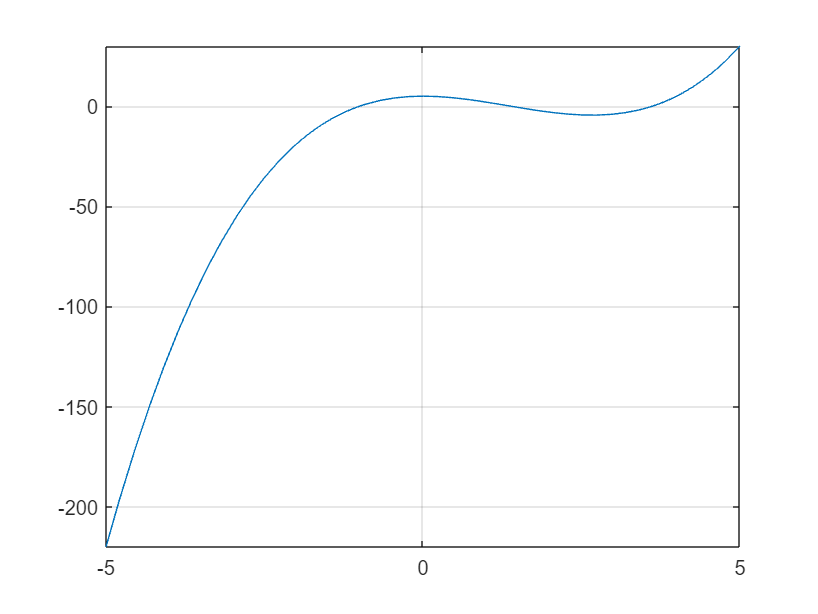

fplot(f)
grid on

Here, then, we will have to use `fzeros` 3 times to find all the roots.

fzero(F,-2)

ans = -1

fzero(F,1)

ans = 1.3820

fzero(F,3)

ans = 3.6180

Note that this is not the cleanest way to numerically solve for the roots of this polynomial--there are special functions defined specifically for finding polynomical roots--but `fzero` is a general function that can be applied to any nonlinear equation.